## Read Geometry Data

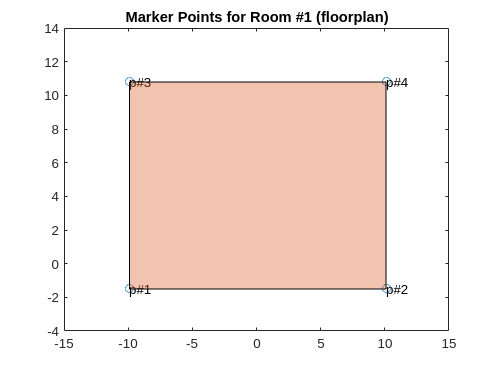

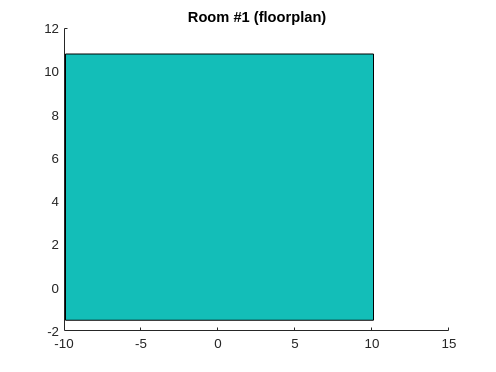

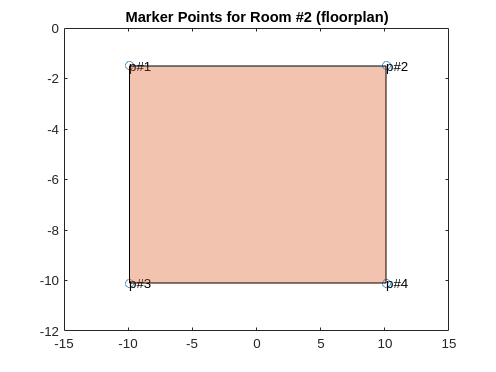

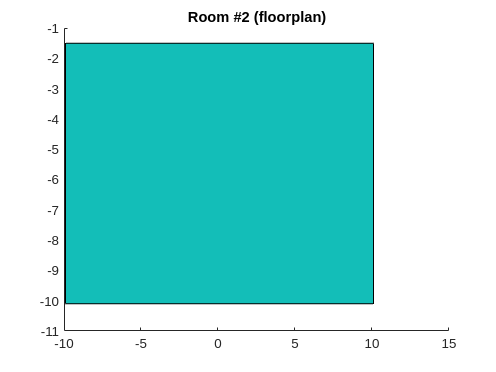

dataBIM = readstruct("buildingSquareShapeTwoRoomsAndDoor.xml");
unitDat = readtable("PhysicalUnitMapping.xlsx",Range="A2:B99");

modelData = readBuildingGeometryData(BuildingData=dataBIM,...
                                     PhysUnitMapping=unitDat,...
                                     Debug=false,RoundOff=1);

clear unitDat

modelData.Room = checkRoomRotationConsistency(Room=modelData.Room);

## Read Material Data

modelData = getWallMaterialDataFromBIM(DataBIM=dataBIM,DataModel=modelData);

## Create Floor Plan

floorPlanStruct = [];

for i = 1:size(modelData.Room,1)
    floorPlanStruct = addRoomToFloorPlan(FloorPlan=floorPlanStruct,...
        Vertex=modelData.Room{i,1}.vertex,...
        Length=modelData.Room{i,1}.len,...
        Width=modelData.Room{i,1}.wid,...
        Angle=modelData.Room{i,1}.rotateByDeg,...
        NewRoom=modelData.Room{i,1}.name,...
        Plot=false);
end

modelApt = defineSingleApartmentUnit(Apartment=floorPlanStruct,Tol=0.01);

% Break Non-rectangular Rooms to Multiple Rectangles
apartment = checkForNonRectangularRooms(Apartment=modelApt,...
                                        Debug=false);

## Get Window Data

% Collate Data for Wall Openings
modelData.Opening = getOpeningForMultipleBuildingWalls(WallList=modelData.WallMaterial.Listing.Wall,...
                                                       ModelData=dataBIM,...
                                                       Debug=false,...
                                                       PhysUnitLen=modelData.UnitLength);

## Apply Internal Window Data

modelData.Opening.IntTbl = getApartmentRoomConnectivity(Apartment=apartment);

% Higher tolerance of 0.05 had to be used
modelData.Opening.IntTbl = updateInternalWallOpeningData(Apartment=apartment,...
    TableData=modelData.Opening.IntTbl,WallData=modelData.Opening.InteriorWall,...
    ModelDataUnit=modelData.UnitLength,Tol=0.05);

    #A     RoomA     #B     RoomB     Solid Wall Fraction
    __    _______    __    _______    ___________________

    1     "room1"    2     "room2"          0.87953      



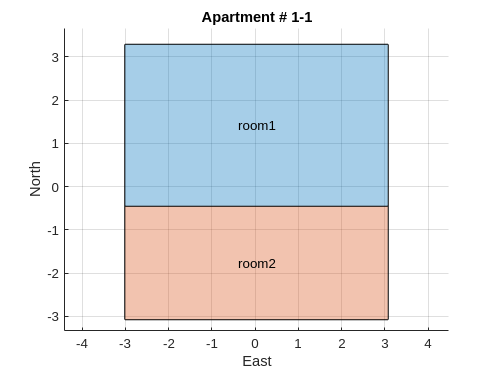


apartment = updateApartmentRoomConnectivity(Apartment=apartment,...
                                            ConnectionTable=modelData.Opening.IntTbl);

floorPlan = defineBuildingFloorPlan(Apartments={apartment});

clear i floorPlanStruct modelApt apartment

figure('Name','Floor Plan Consolidated');
plotFloorPlanLayout(PlotData=floorPlan,Type="floorplan")

## Apply External Window Data

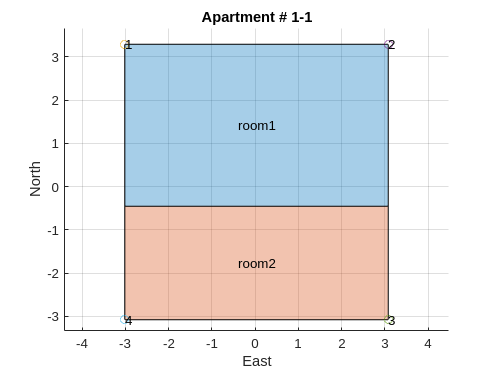

*** Default window and vent data
 
    From Point    To Point    Wall of Room    Window (0-1)    Vent (0-1)    Wall Index
    __________    ________    ____________    ____________    __________    __________

        1            2          "room1"            0              0         "[1 1 2]" 
        2            3          "room1"            0              0         "[1 1 3]" 
        2            3          "room2"            0              0         "[1 2 3]" 
        3            4          "room2"            0              0         "[1 2 4]" 
        4            1          "room1"            0              0         "[1 1 1]" 
        4            1          "room2"            0              0         "[1 2 1]" 

 
Use function addOpeningOnWallSection() to add windows or vent

modelData.Opening.ExtTbl = visualizeBuildingWallsToAddWindowsVents(FloorPlan=floorPlan,Plot=true);


% Update Table Data - Exterior Walls
modelData.Opening.ExtTbl = updateWindowVentTableData(FloorPlan=floorPlan,...
    WallData=modelData.Opening.ExteriorWall,TableData=modelData.Opening.ExtTbl,...
    ModelDataUnit=modelData.UnitLength,Tol=0.01);

disp(modelData.Opening.ExtTbl);

    From Point    To Point    Wall of Room    Window (0-1)    Vent (0-1)    Wall Index
    __________    ________    ____________    ____________    __________    __________

        1            2          "room1"         0.43701           0         "[1 1 2]" 
        2            3          "room1"         0.43701           0         "[1 1 3]" 
        2            3          "room2"         0.30841           0         "[1 2 3]" 
        3            4          "room2"         0.30841           0         "[1 2 4]" 
        4            1          "room1"         0.43701           0         "[1 1 1]" 
        4            1          "room2"         0.30841           0         "[1 2 1]" 



% modelData.Opening.ExtTbl.("Window (0-1)")(:,1)=0.2;
updatedFloorPlan = addOpeningOnWallSection(FloorPlan=floorPlan,...
                                           Data=modelData.Opening.ExtTbl);
clear floorPlan

## Create Building

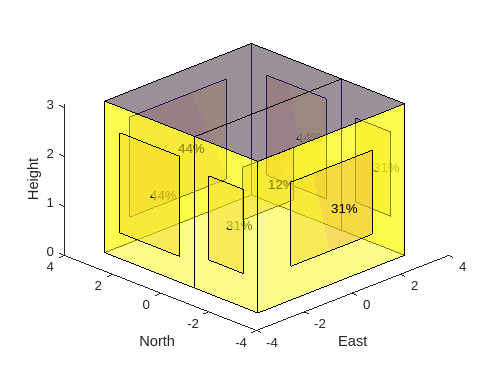

viewingAngle = [-1 -1 1]; 

building = generateBuilding3Dlayout(BuildingName="BuildingUnit",...
                                    BuildingFloorPlan=updatedFloorPlan,...
                                    NumberOfLevels=modelData.NumLevels,...
                                    LevelHeight=modelData.Height,...
                                    Tol=0.01);

figure('Name','BuildingUnit Elevation');
plot3DlayoutBuilding(Building=building,...
                     PlotViewDirection=viewingAngle,...
                     ColorScheme="simple",...
                     InternalWalls=true,...
                     DebugMode=true);


clear updatedFloorPlan viewingAngle